# Example usage of XPLOR and MLspike

Geographical data from the Nasa Earth Observations archive at https://neo.sci.gsfc.nasa.gov/archive/geotiff.float/

Thomas Deneux, 09/04/2020

## Load data

Note: executing this script will not download nor read any data, except for the Readme.txt. It will list the data already downloaded. To download more data or read downloaded data, execute from inside the "if eval('false')" block of the relevant section.

### Base file and url folders

base_folder = fullfile(fileparts(which('xplor')),'demo','nasa_neo');
fn_mkdir(base_folder);
base_url = 'https://neo.sci.gsfc.nasa.gov/archive/geotiff.float/';

### Download Readme

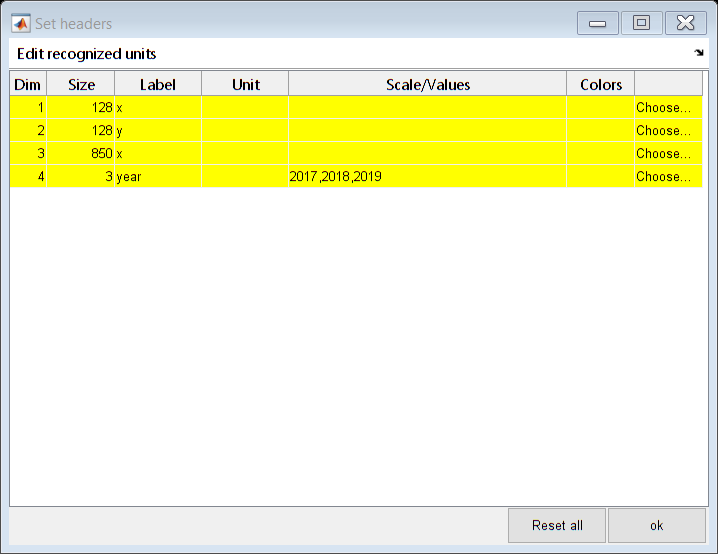

file_readme = fullfile(base_folder,'README.txt');

if ~exist(file_readme,'file')
    url_readme = 'https://neo.sci.gsfc.nasa.gov/archive/geotiff.float/README.txt';
    websave(file_readme,url_readme)
end

### Scan Readme to obtain image types and details

% read Readme.txt
file_readme = fullfile(base_folder,'README.txt');
readme = fn_readtext(file_readme);

% process: separate lines, skip headers
% readme = strsplit(readme,'\n');
nheader = fn_find(@(str)strfind(str,'-------------'),readme,'first');
readme(1:nheader) = [];

% retrieve types and descriptions
nalltype = length(readme);
alltypes = cell(1,nalltype);
alltypes_descriptions = cell(1,nalltype);
for i = 1:nalltype
    [alltypes{i}, alltypes_descriptions{i}] = fn_regexptokens(readme{i},'^([^ ]*) +(.*[^ ]) *$');
end

### Manual list of datasets with 1 image per month

monthly_types = { ...
    'AMSRE_SSTAn_M'    ... Sea Surface Temperature Anomaly 2002-2011 (1 month - Aqua/AMSR-E)

ans =    850    12


    'AQUARIUS_SSS_M'   ... Sea Surface Salinity 2011-2015 (1 month)
    'AURA_NO2_M' ...       Nitrogen Dioxide (1 month)   
    'AURA_OZONE_M'     ... Ozone (1 month)
    'AURA_UVI_CLIM_M'  ... UV Index

ans =    850     4


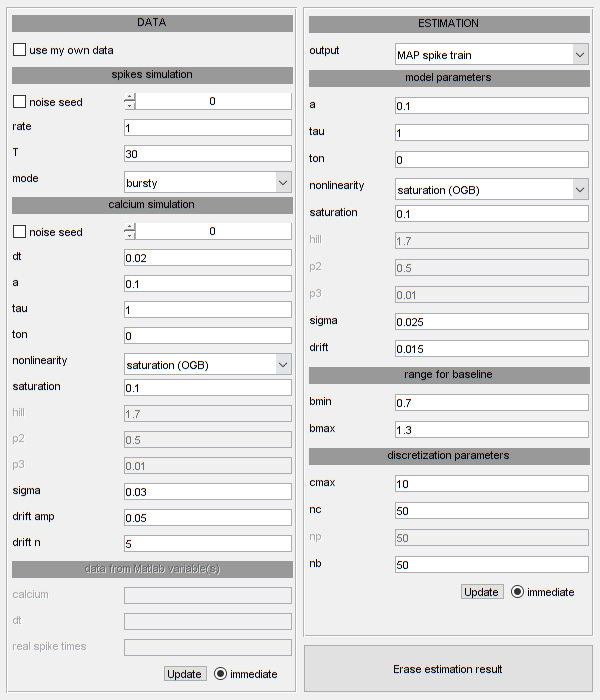

estimate drifting baseline


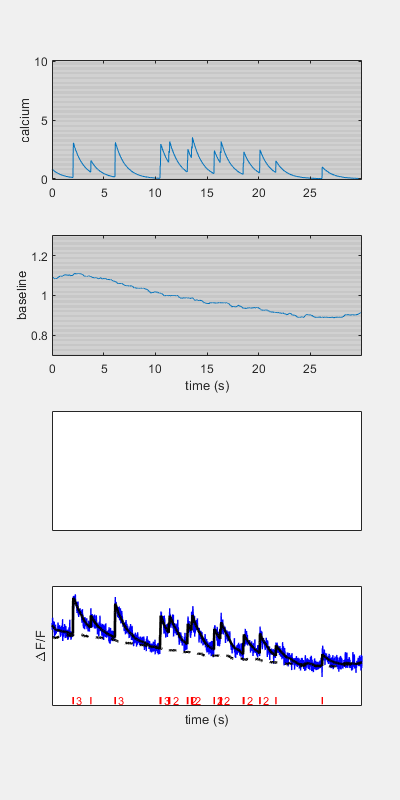

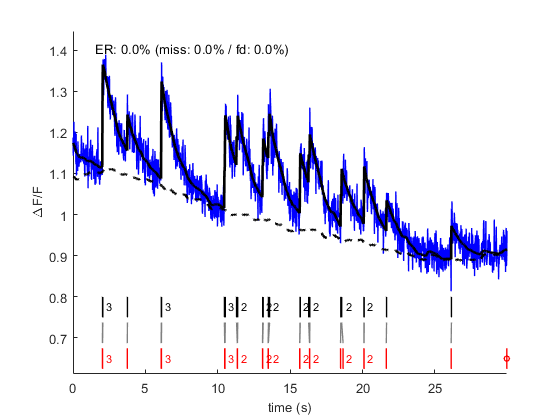

ans =   spk_demoGUI with properties:

    data: [1×1 struct]
     res: [1×1 struct]
    pgen: [1×1 struct]
    pcal: [1×1 struct]
    pest: [1×1 struct]


    'AVHRR_CLIM_M'     ... Average Sea Surface Temperature 1985-1997 (1 month - AVHRR)
    'AVHRR_SST_M'      ... Sea Surface Temperature 1981-2006 (1 month - AVHRR)
    'CERES_INSOL_M'    ... Solar Insolation (1 month)
    'CERES_LWFLUX_M'   ... Outgoing Longwave Radiation (1 month)

    'CERES_NETFLUX_M'  ... Net Radiation (1 month)
    'CERES_SWFLUX_M'   ... Reflected Shortwave Radiation (1 month)
    'GISS_TA_M'        ... Global Temperature Anomaly (1 month)
    'GRACE_LWE_M'      ... Water Equivalent Anomaly 2002-2017 (1 month)
    'MOD10C1_M_SNOW'   ... Snow Cover (1 month - Terra/MODIS)
    'MOD14A1_M_FIRE'   ... Active Fires (1 month - Terra/MODIS)

ans =    850     4


    'MOD15A2_M_LAI'    ... Leaf Area Index (1 month - Terra/MODIS)
    'MOD17A2_M_PSN'    ... Net Primary Productivity (1 month - Terra/MODIS)
    'MODAL2_M_AER_OD'  ... Aerosol Optical Thickness (1 month - Terra/MODIS)
    'MODAL2_M_AER_RA'  ... Aerosol Particle Radius (1 month - Terra/MODIS, 2005-16)
    'MODAL2_M_CLD_FR'  ... Cloud Fraction (1 month - Terra/MODIS)
    'MODAL2_M_CLD_OT'  ... Cloud Optical Thickness (1 month - Terra/MODIS)
    'MODAL2_M_CLD_RD'  ... Cloud Particle Radius (1 month - Terra/MODIS)
    'MODAL2_M_CLD_WP'  ... Cloud Water Content (1 month - Terra/MODIS)
    'MODAL2_M_SKY_WV'  ... Water Vapor (1 month - Terra/MODIS)
    'MOD_LSTAD_M'      ... Land Surface Temperature Anomaly [Day] (1 month)
    'MOD_LSTAN_M'      ... Land Surface Temperature Anomaly [Night] (1 month)
    'MOD_LSTD_CLIM_M'  ... Average Land Surface Temperature [Day] (1 month)
    'MOD_LSTD_M'       ... Land Surface Temperature [Day] (1 month - Terra/MODIS)
    'MOD_LSTN_CLIM_M'  ... Average Land Surface Temperature [Night] (1 month)
    'MOD_LSTN_M'       ... Land Surface Temperature [Night] (1 month - Terra/MODIS)
    'MOD_NDVI_M'       ... Vegetation Index (1 month - Terra/MODIS)
    'MOP_CO_M'         ... Carbon Monoxide (1 month - Terra/MOPITT)
    'MWOI_SST_M'       ... Sea Surface Temperature 1998+ (1 month MWOI)
    'MY1DMM_CHLORA'    ... Chlorophyll Concentration (1 month - Aqua/MODIS)
    'MYD28M'           ... Sea Surface Temperature (1 month - Aqua/MODIS)
    'MYDAL2_M_AER_OD'  ... Aerosol Optical Thickness (1 month - Aqua/MODIS)
    'MYDAL2_M_AER_RA'  ... Aerosol Particle Radius (1 month - Aqua/MODIS, 2002-16)
    'MYDAL2_M_CLD_FR'  ... Cloud Fraction (1 month - Aqua/MODIS)
    'MYDAL2_M_CLD_OT'  ... Cloud Optical Thickness (1 month - Aqua/MODIS)
    'MYDAL2_M_CLD_RD'  ... Cloud Particle Radius (1 month - Aqua/MODIS)
    'MYDAL2_M_CLD_WP'  ... Cloud Water Content (1 month - Aqua/MODIS)
    'MYDAL2_M_SKY_WV'  ... Water Vapor (1 month - Aqua/MODIS)
    'SWE_M'            ... Snow Water Equivalent (1 month - Passive Microwave, with optical)
    'TRMM_3B43M'       ... Rainfall (1 month - TRMM)
    };

ans =     23   850     3


### Download full datasets!

if eval('false')
    %% (go inside this block to execute)

ans =    850    23     3


    
    % select datasets to download
    dowload_types = monthly_types;

ans =    850    23     3



    % download loop
    for type = dowload_types
        type_str = type{1}; % Get type as a string

par = struct with fields:
                dt: []
                F0: []
                 a: 0.1000
               tau: 1
               ton: 0
        saturation: 0
           pnonlin: []
              hill: 1
                c0: 0
             drift: [1×1 struct]
          finetune: [1×1 struct]
              algo: [1×1 struct]
           special: [1×1 struct]
           display: 'default'
    dographsummary: 1


        subfolder = fullfile(base_folder,type_str);
        fn_mkdir(subfolder) % Create folder in current Matlab path

        % list from web folder all files belonging to this dataset
        listing = webread([base_url type_str]);
        filenames = regexp(listing,[type_str '[a-zA-Z_\-0-9]*\.FLOAT\.TIFF'],'match');
        if isempty(filenames)

par = struct with fields:
                dt: 0.1689
                F0: [0.7000 1.3000]
                 a: 0.1100
               tau: 1.8700
               ton: 0
        saturation: 0
           pnonlin: [0.8100 -0.0560]
              hill: 1
                c0: 0
             drift: [1×1 struct]
          finetune: [1×1 struct]
              algo: [1×1 struct]
           special: [1×1 struct]
           display: 'default'
    dographsummary: 1


            disp(['no file found for data set ' type_str])
        end

tps_mlspike  1/69


 2/69


 3/69


 4/69


 5/69


 6/69


 7/69


 8/69


 9/69


10/69


11/69


12/69


13/69


14/69


15/69


16/69


17/69


18/69


19/69


20/69


21/69


22/69


23/69


24/69


25/69


26/69


27/69


28/69


29/69


30/69


31/69


32/69


33/69


34/69


35/69


36/69


37/69


38/69


39/69


40/69


41/69


42/69


43/69


44/69


45/69


46/69


47/69


48/69


49/69


50/69


51/69


52/69


53/69


54/69


55/69


56/69


57/69


58/69


59/69


60/69


61/69


62/69


63/69


64/69


65/69


66/69


67/69


68/69


69/69


spikes = 1×69 cell array
    {1×106 double}    {1×126 double}    {1×41 double}    {1×70 double}    {1×110 double}    {1×62 double}    {1×71 double}    {1×56 double}    {1×117 double}    {1×118 double}    {1×55 double}    {1×110 double}    {1×100 double}    {1×135 double}    {1×150 double}    {1×117 double}    {1×49 double}    {1×152 double}    {1×73 double}    {1×54 double}    {1×133 double}    {1×134 double}    {1×118 double}    {1×110 double}    {1×149 double}    {1×41 double}    {1×42 double}    {1×125 double}    {1×48 double}    {1×98 double}    {1×44 double}    {1×113 double}    {1×107 double}    {1×46 double}    {1×102 double}    {1×130 double}    {1×132 double}    {1×158 double}    {1×121 double}    {1×71 double}    {1×149 double}    {1×80 double}    {1×82 double}    {1×139 double}    {1×127 double}    {1×122 double}    {1×113 double}    {1×125 double}    {1×49 double}    {1×62 double}    {1×120 double}    {1×49 double}    {1×73 double}    {1×68 double}    {1×118 double}    {1×1

fit = 850×69 single matrix
    0.7175    0.7485    0.7025    0.7000    0.7025    0.7113    0.7063    0.7000    0.7000    0.7000    0.7025    0.7000    0.7025    0.7000    0.7025    0.7025    0.7000    0.7000    0.7025    0.7000    0.7000    0.7063    0.7025    0.7000    0.7113    0.7000    0.7025    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7025    0.7000    0.7063    0.7000    0.7025    0.7176    0.7063    0.7000    0.7000    0.7025    0.7000    0.7000    0.7025    0.7063    0.7000    0.7147    0.7113
    1.0398    0.8434    0.9856    0.7770    0.7068    0.8271    0.8089    0.9611    0.9531    0.7039    0.9849    0.7786    0.7948    0.7032    0.7023    0.9781    0.9626    0.9529    0.9821    0.9594    0.7000    0.7090    0.7023    0.7008    0.8239    0.9575    0.9809    0.9541    0.9611    1.2038    0.9576    0.9533    0.7025    0.9811    0.9583    1.0018    0.9529    0.7023    0.8400    1.0038    0.9529    0.9529    0.9803    0.7000    0.7035    0.7023    1.0029  

drift = 850×69 single matrix
    0.7061    0.7485    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7121    0.7000
    0.7167    0.7598    0.7090    0.7000    0.7045    0.7087    0.7053    0.7060    0.7002    0.7039    0.7085    0.7014    0.7047    0.7032    0.7000    0.7035    0.7071    0.7000    0.7064    0.7048    0.7000    0.7033    0.7000    0.7008    0.7060    0.7034    0.7055    0.7009    0.7061    0.7012    0.7034    0.7003    0.7025    0.7057    0.7040    0.7055    0.7000    0.7000    0.7069    0.7068    0.7000    0.7000    0.7051    0.7000    0.7035    0.7000    0.7062

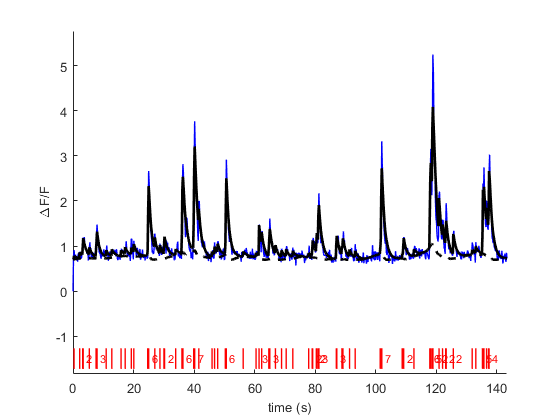


        % download loop
        nfile = length(filenames);
        fn_progress(type_str, nfile)
        for k = 1:nfile
            fn_progress(k)
            filename = filenames{k};
            url = [base_url type_str '/' filename];
            file = fullfile(subfolder, filename);
            if exist(file,'file'), ok = true; continue, end % file already downloaded
            try
                saved = websave(file, url); % Save as files

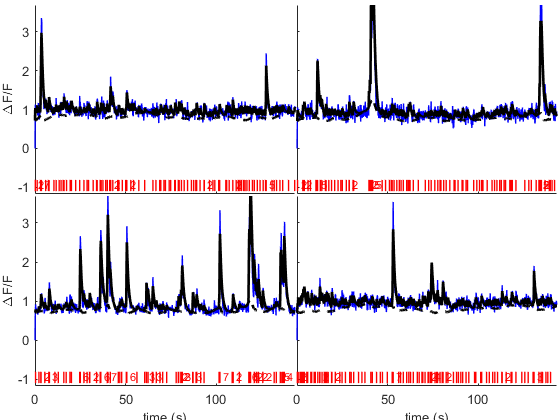

            catch webread_exception
                error(['url ' url ' not found'])
            end
        end

    end
    
end

### Download specific files

if eval('false')
    %% (go inside this block to execute)
    
        % select specific types to download and years range
    types = {'MOD_LSTAD_M' 'MOD_LSTAN_M' 'MOD_LSTD_M' 'MOD_LSTN_M'};
    years_range = 2017:2019;

    % download loop
    for type = types
        type_str = type{1}; % Get type as a string
        subfolder = fullfile(base_folder,type_str);
        fn_mkdir(subfolder) % Create folder in current Matlab path
        n_dates = 1;
        for year = years_range
            for month = 1:12
                file = [type_str '_' num2str(year) '-' num2str(month,'%02d') '.FLOAT.TIFF']; % File formatted as MOP_CO_M_2013-10.TIFF
                url = [base_url type_str '/' file];
                file = fullfile(subfolder, file);
                if exist(file,'file'), continue, end % file already downloaded
                try
                    %data(:,:,n_dates) = webread(strcat(url, file)); % Read
                    saved = websave(file, url); % Save as files
                    disp(['saved ' file])
                catch webread_exception
                    if strcmp(webread_exception.identifier, 'MATLAB:webservices:HTTP404StatusCodeError')
                        disp(['url ' url ' not found, skipping...'])
                        continue;
                    end
                end
                n_dates = n_dates + 1;
            end
        end
    end

end

### Check years available for each type

% get year range by scanning which first and last file of each folder
alltypes_years_range = struct;
alltypes_empty = false(1,nalltype);
for ktype = 1:nalltype
    type_str = alltypes{ktype}; % Get type as a string
    subfolder = fullfile(base_folder,type_str);
    d = dir(fullfile(subfolder,'*.TIFF'));
    if isempty(d), alltypes_empty(ktype) = true; continue, end
    first_year = str2double(fn_regexptokens(d(1).name,[type_str '_(\d{4})']));
    last_year = str2double(fn_regexptokens(d(end).name,[type_str '_(\d{4})']));
    alltypes_years_range.(type_str) = [first_year last_year];
end
disp(alltypes_years_range)

### Read data

if eval('false')
    %% (go inside this block to execute)
    
    % select types
    types = alltypes(~alltypes_empty);
    types = {'MOD_LSTD_M'}; % land temperature day
%     types = {'MOD10C1_M_SNOW'}; % snow
    ntype = length(types);

    % types descriptions
    desc = fn_map(@(type)alltypes_descriptions{strcmp(type,alltypes)},types);

    % code below selects all available years for the selected types
    years_range = fn_map(@(type)alltypes_years_range.(type),types','array');
    years_range = [min(years_range(:,1)) max(years_range(:,2))];

    % subselect years range
    %     years_range(1) = max(years_range(1),2000);
    fprintf('years range: from %i to %i\n',years_range)
    years_range = years_range(1):years_range(2);
    nyear = length(years_range);

    % subselect months range or keep the default 1:12
    months_range = 1:12;
    %     months_range = [1 7]; % January and July
    nmonth = length(months_range);

    % spatial binning
    nx = 3600/5;
    ny = 1800/5;

    % array
    clear data
    data = NaN([nx ny nmonth nyear ntype]);

    fn_progress('reading file',ntype*nmonth*nyear)
    kfile = 0;
    for ktype = 1:ntype    
        type_str = types{ktype}; % Get type as a string
        disp(['Load ' desc{ktype}])
        subfolder = fullfile(base_folder,type_str);
        for kyear = 1:nyear
            year = years_range(kyear);
            for kmonth = 1:nmonth
                month = months_range(kmonth);
                kfile = kfile + 1;
                fn_progress(kfile)
                file = [type_str '_' num2str(year) '-' num2str(month,'%02d') '.FLOAT.TIFF']; % File formatted as MOP_CO_M_2013-10.TIFF
                file = fullfile(subfolder,file);
                if exist(file,'file')
                    x = fn_readimg(file);
                    % undefined data: replace 99999 by NaN
                    x(x==99999) = NaN;
                    % bin
                    x = fn_bin(x,[-nx -ny]);
                    % put in array
                    data(:,:,kmonth,kyear,ktype) = x;
                else
                    %fprintf('missing data for type %s, month %.2i/%i\n',type_str,month,year);
                end
            end
        end
    end

end

## Explore data with XPLOR

xplor x

fill the table as above; for the scales:

- in the `x` and `y` lines type `300/128` and it will calculate the pixel size in micron

- in the `time` line type `1/5.92` and it will calculate the time period in second

then press ok, you should obtain:

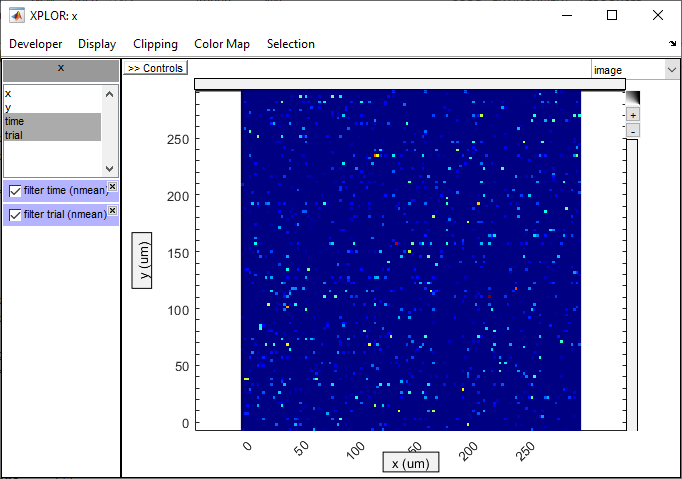

## Raise a second window

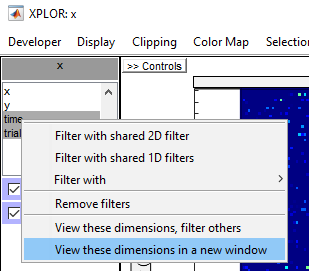

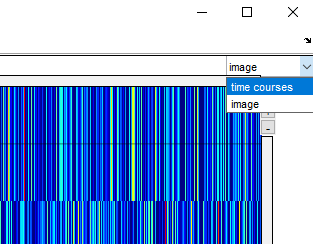

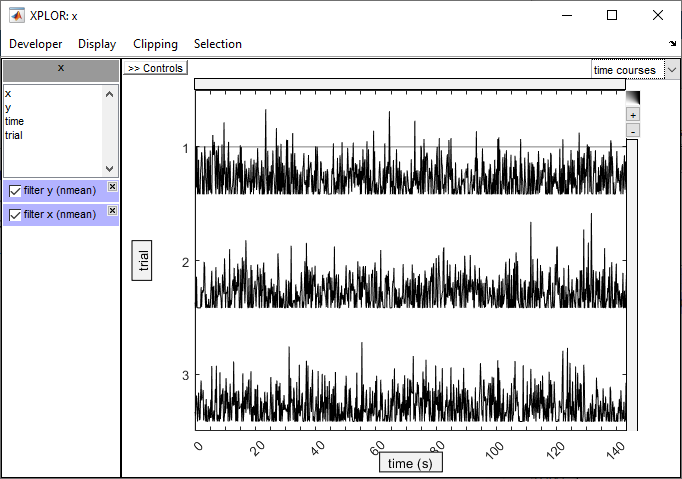

## Link the two windows together

Follow the screenshots to have each window controling the filters that select what is displayed in the other window.

1) First the time course window will control temporal selection, so we can see an average image in the image window:

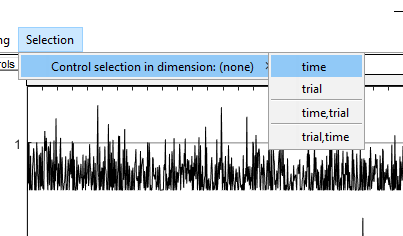

Trace a large selection by right-click and draw the mouse inside the window (result is the blue rectangle below; if you are not satisfied with your selection you can remove it with menu `Selection > Clear selections` and restart).

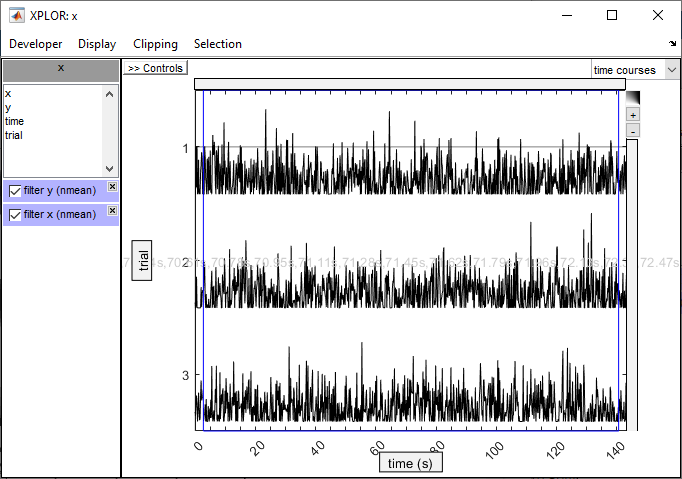

The image window now shows an average image!

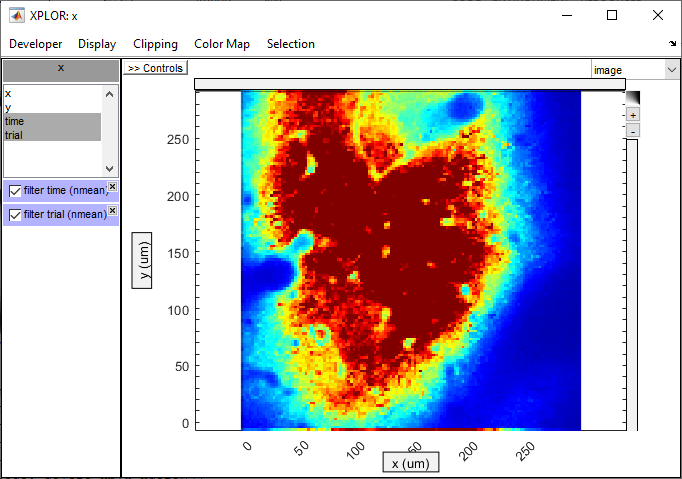

To improve the display:

- change the color map in the `Color Map` menu

- perform auto-clip either with the menu `Clipping > Do Auto-Clip` or by double-clicking on the small black&white button in the top-right corner  

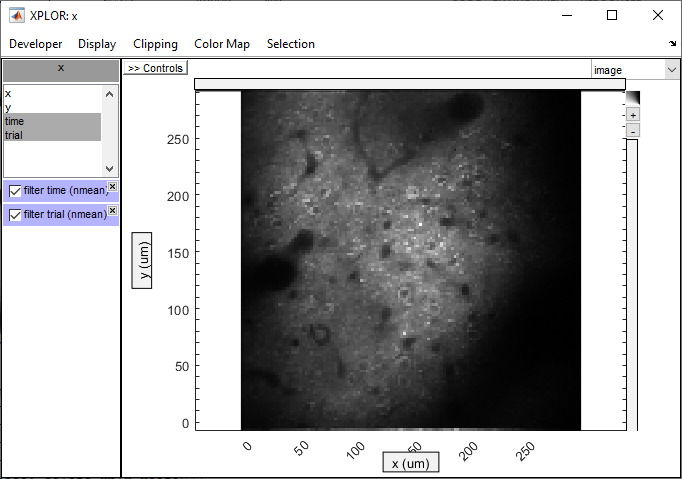

2) Now control 2D ROIs in the image window whose time courses will be shown in the other window

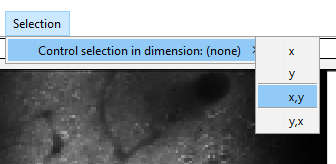

Right-clik in the window and drag to make selections. Note also that you can zoom in with the left button and adjust the clipping with the black&white button:

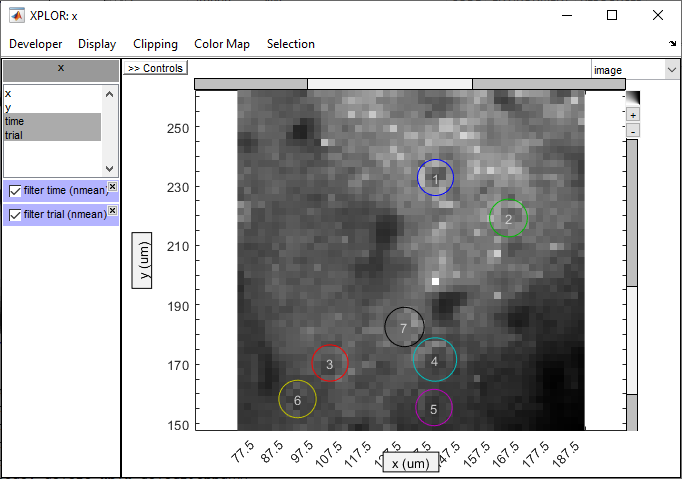

Now in the other window apply this "x-y ROI filter":

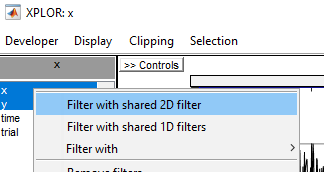

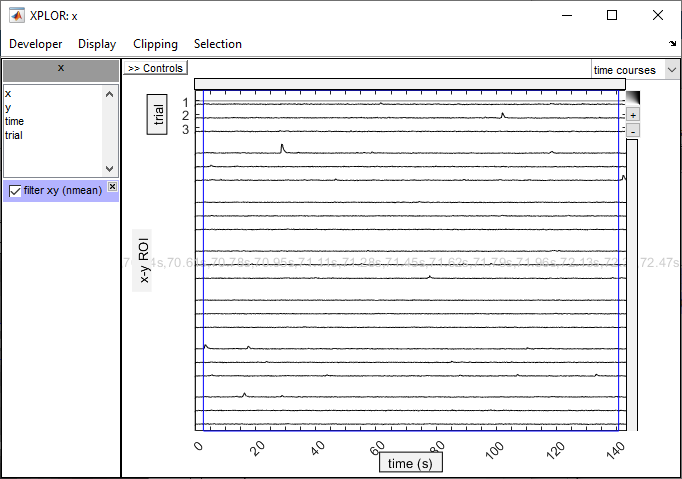

You can improve the display:

- drag the `trial` label to the x-axis

- menu `Clipping > Adjust > Adjust each element by its Mean Value`

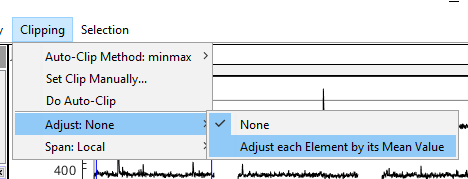

- adjust the clipping range with the black&white button, or with the + and - signs.

- make sure the `time` label is selected and drag the zoom slider above the graph to hide the first time values which are not interesting

- filter `trials and select which trial you want to look at`

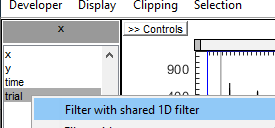

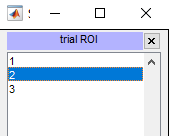

You should obtain this:

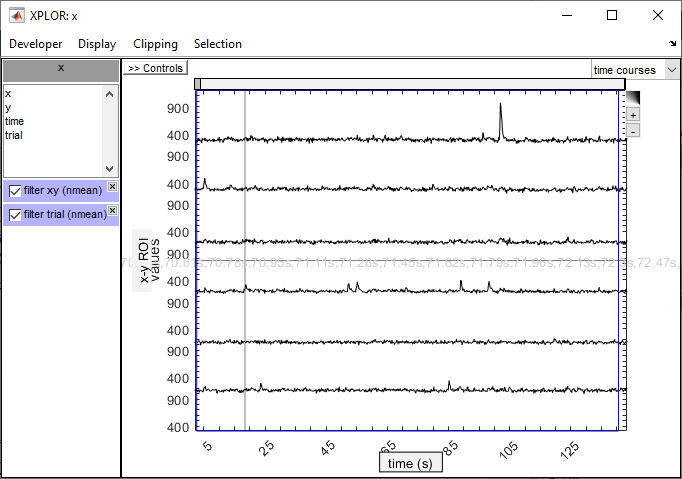

## Select the clearly active neurons

Clear for some moment the time selection, and drag the time cursor to have individual frames playing in the image window.

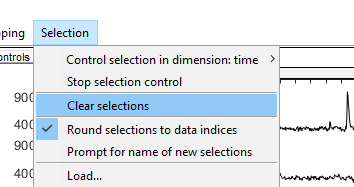

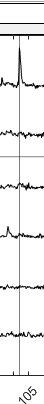

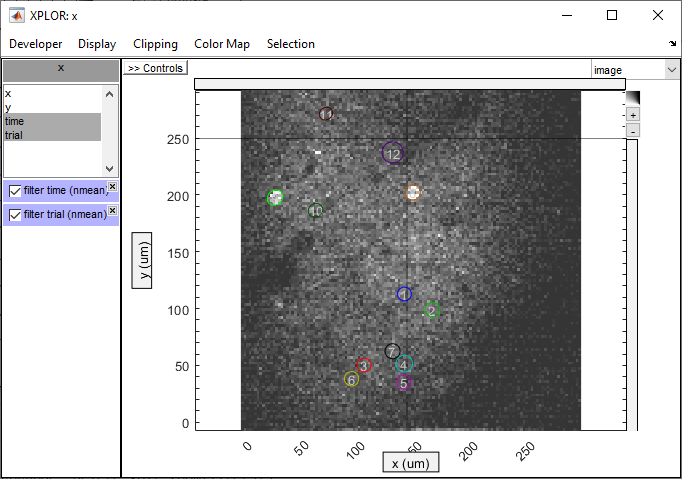

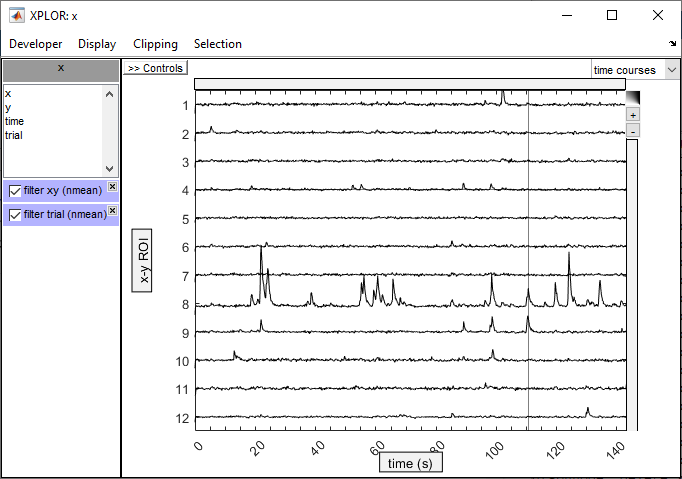

## Get the time courses of the selected neuron ROIs

y = V.slice.data';
size(y)

Here we have 12 regions, each with a time courses of 850 time points.

We can subselect only a subset for the moment:

y = y(:,[6 7 8 9]);
size(y)

## Test spike estimation on this data with spk_demoGUI

Start `spk_demoGUI`, this runs estimation on a simulated data set.

spk_demoGUI

## Load your data into spk_demoGUI

WARNING you need first to divide each time courses by its average value!

In recent versions of Matlab you can do like this:

y = y ./ mean(y,1);
size(y)

Then do the following:

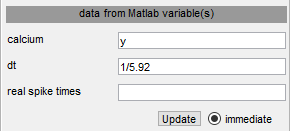

Change from OGB to GCaMP nonlinearity:

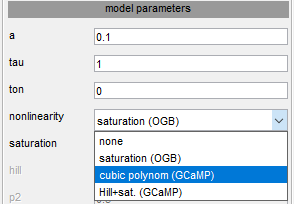

Here is a first result:

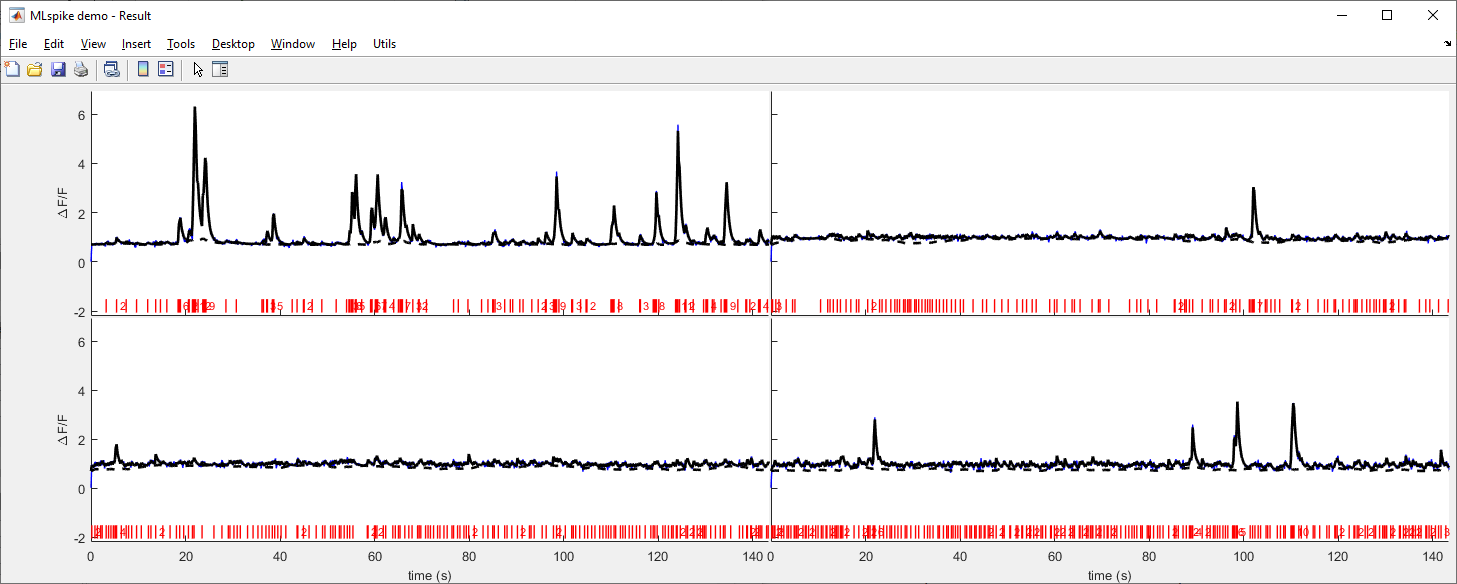

## Fine-tune MLspike parameters

Let's put parameters for GCamp6s from fig. S6 in the MLspike paper.

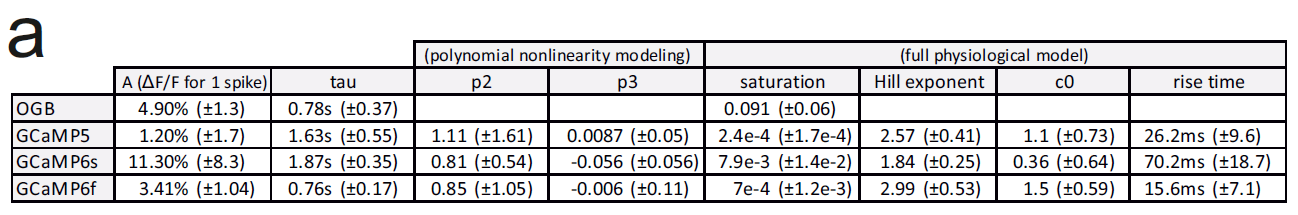

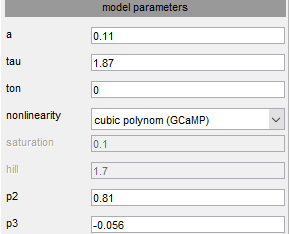

Also, a closer inspection reveals that there are probably too many spikes estimated (false positives). In the screenshot below indeed spikes have been assigned to what is probably only noise.

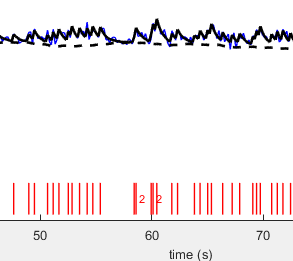

We can increase the a priori noise level:

This looks better

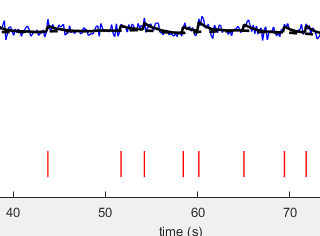

Depending on the analysis performed thereafter one might want to make even more sure that there are no false positives and further increase the a priori noise level.

Let us consider that this is good enough.

## Get neuron traces for all neurons and all trials

For now we have selected neurons using XPLOR. Of course more sophisticated tools might be needed to select automatically and more precisely a larger number of neurons. Let us however continue with XPLOR for the moment.

We gather all our data by now selecting all the trials.

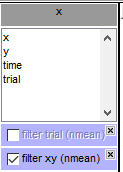

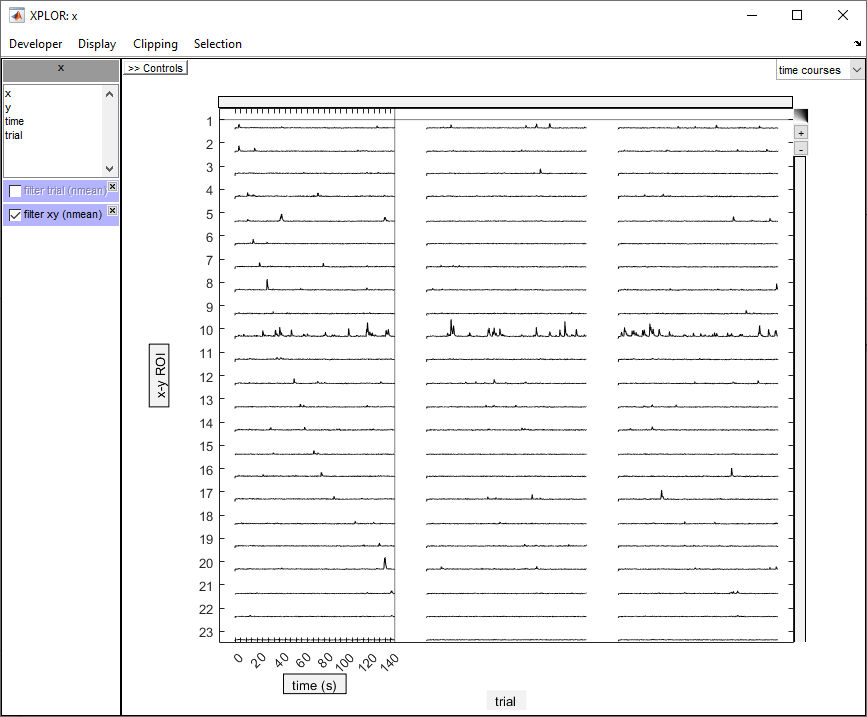

Get the data:

y = V.slice.data;
size(y)

Reorganize from neuron*time*trial to time*neuron*trial

y = permute(y,[2 1 3]);
size(y)

Divide each trace by its average.

y = y ./ mean(y,1);
size(y)

## Write your own script with MLspike

Build a set of parameters for MLspike with the parameter values we have found.

par = spk_est('par')
par.dt = 1/5.92;
par.a = 0.11;
par.tau = 1.87;
par.pnonlin = [0.81 -0.056];
par.finetune.sigma = 0.05;
par.drift.parameter = 0.015;
par.F0 = [0.7 1.3]

Run the estimation for all traces!

[spikes, fit, drift] = spk_est(y,par)
% reshape
[nt, ncell, ntrial] = size(y);
spikes = reshape(spikes,[ncell, ntrial]);
fit = reshape(fit,[nt, ncell, ntrial]);
drift = reshape(drift,[nt, ncell, ntrial]);

## View result

View result for a specific cell and trial.

kcell = 10;
ktrial = 1;
clf
spk_display(par.dt,spikes(kcell,ktrial), {y(:,kcell,ktrial) fit(:,kcell,ktrial), drift(:,kcell,ktrial)})

Or for a few cells, etc.

kcell = [1 5 10 12];
ktrial = 1;
spk_display(par.dt,spikes(kcell,ktrial), {y(:,kcell,ktrial) fit(:,kcell,ktrial), drift(:,kcell,ktrial)})

Maybe parameter `par.finetune.sigma` could still be decreased are there seams to still be too many estimated spikes...